# Image surface

The accommodative state of an eye is expressed in diopters (D). A given accommodation implies that points in object space, at a distance 1/D meters from the principal point of the eye, will be in optimal focus on the retina. This set of points in object space are distributed as on the surface of a sphere, and may be termed the object surface. For any given point from the object surface, we may obtain the internal focal point. The set of internal focal points that derive from the object surface form the *image surface*.

These ideas are discussed in:

- Liu, Tao, Vidhyapriya Sreenivasan, and Larry N. Thibos. "[Uniformity of accommodation across the visual field](https://jov.arvojournals.org/article.aspx?articleid=2488411)." *Journal of Vision* 16.3 (2016): 6-6.

In this demonstration we will examine the image surface for an eye that is accommodated to a distance of 1 meter. The eye has stigmatic but centered optical elements.

First we create the eye, imaged at 555 nm.

accommodation = 1; % Focused at 1 meter distance
kvals = [43.3990, 44.3365 0 0 0]; % Stigmatic, unrotated cornea
eye = modelEyeParameters('spectralDomain',555,'accommodation',accommodation,'kvals',kvals);

When we define visual field positions below, we will do so with respect to these reference points:

incidentNode = eye.landmarks.incidentNode.coords;
principalPoint = calcPrincipalPoint(eye);
objectDistance = 1000/accommodation; % in mm

Generate and plot the optical system:

opticalSystem = assembleOpticalSystem(eye,'surfaceSetName','mediumToRetina');
figure
plotOpticalSystem('newFigure',false,'surfaceSet',opticalSystem,'addLighting',true);
title('Image surface')
xlabel('axial [mm]'); ylabel('horizontal [mm]'); zlabel('vertical [mm]')
hold on

Now loop over visual field positions and plot the focal points, color coded by the distance with which the focal point misses the surface of the retina (yellow >= 1 mm).

S = eye.retina.S;
eFP = [];
iFP = [];
cFP = [];
for hh = -40:40
    for vv = -40:40
        [iFP(:,end+1),~,rp] = calcInternalFocalPoint(opticalSystem,[hh vv],objectDistance,incidentNode,principalPoint);
        fpError = quadric.distancePointEllipsoid(iFP(:,end),S);
        eFP(:,end+1)=rp(:,1);
        cFP(end+1,:) = [1 min([1 fpError]) 0];
    end
end

Add the image surface 

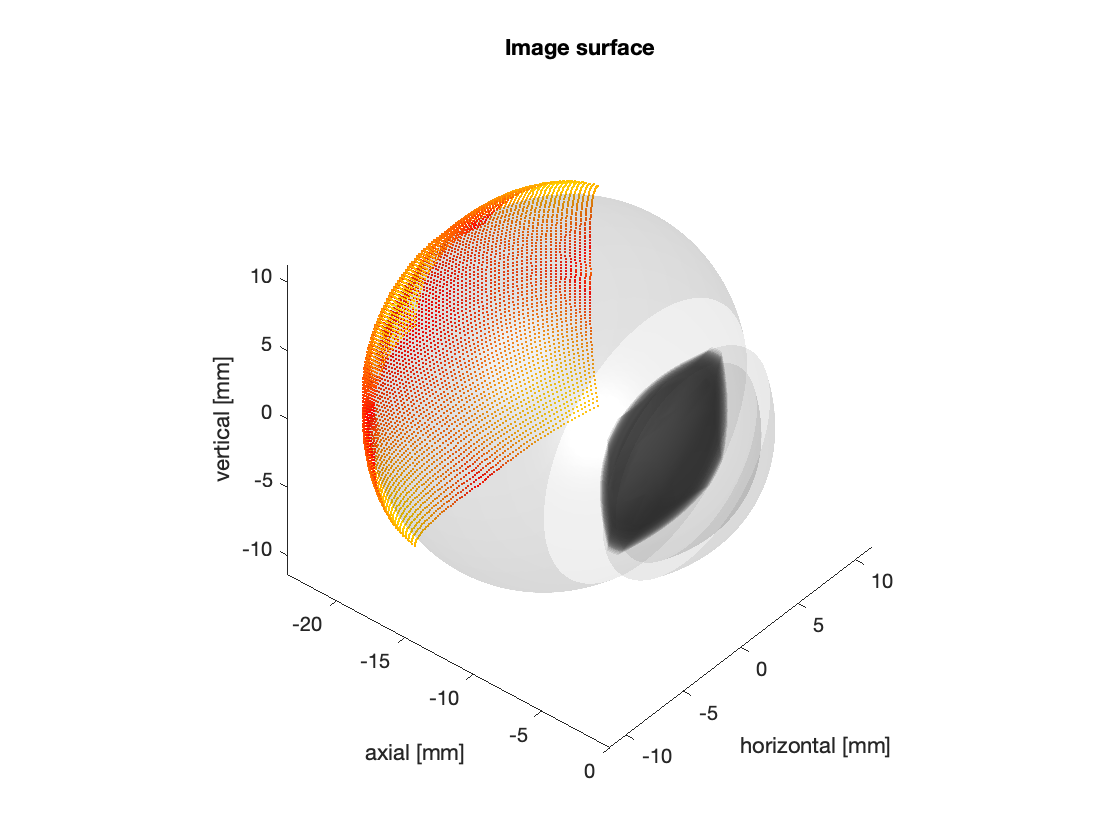

scatter3(iFP(1,:),iFP(2,:),iFP(3,:),1,cFP,'.')

Plot the image and object surface

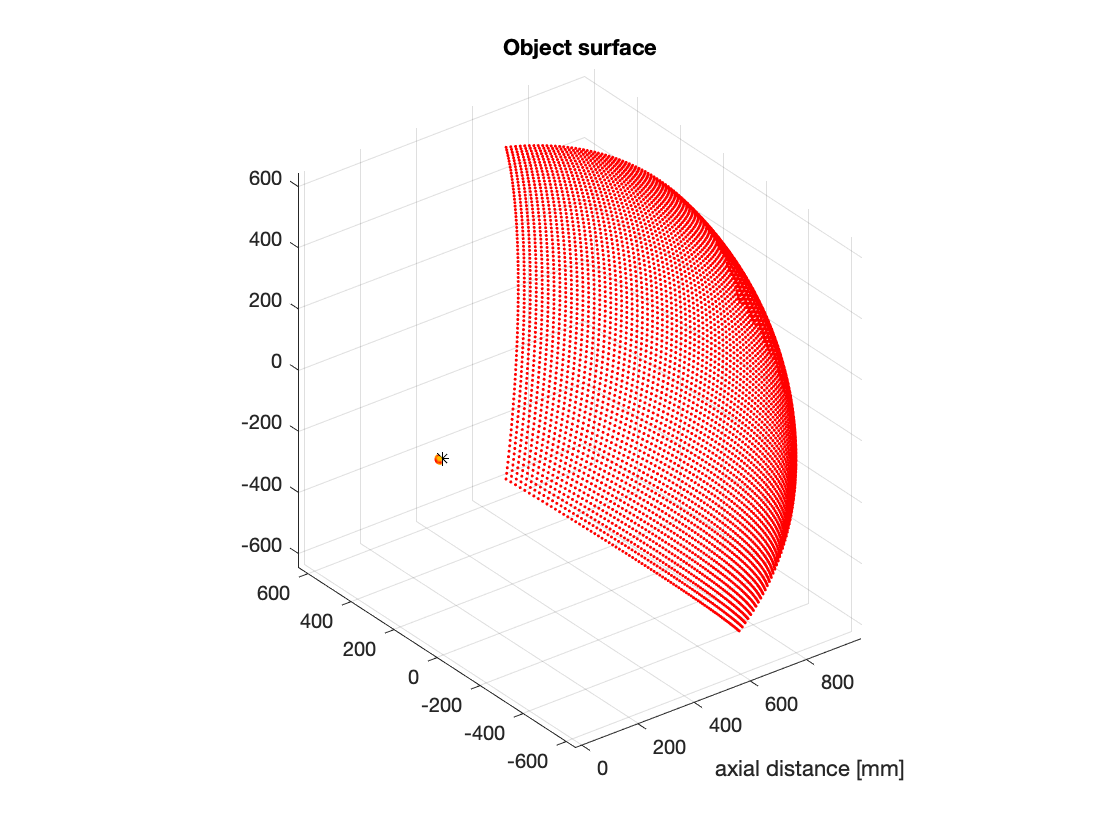

figure
scatter3(iFP(1,:),iFP(2,:),iFP(3,:),1,cFP,'.')
hold on
scatter3(eFP(1,:),eFP(2,:),eFP(3,:),1,'r','.')
plot3(principalPoint(1),principalPoint(2),principalPoint(3),'*k')
xlabel('axial distance [mm]')
title('Object surface')
axis equal